МИНИСТЕРСТВО ОБРАЗОВАНИЯ И НАУКИ РФ

ФЕДЕРАЛЬНОЕ ГОСУДАРСТВЕННОЕ АВТОНОМНОЕ ОБРАЗОВАТЕЛЬНОЕ УЧРЕЖДЕНИЕ ВЫСШЕГО ОБРАЗОВАНИЯ “САНКТ-ПЕТЕРБУРГСКИЙ НАЦИОНАЛЬНЫЙ ИССЛЕДОВАТЕЛЬСКИЙ УНИВЕРСИТЕТ

ИНФОРМАЦИОННЫХ ТЕХНОЛОГИЙ, МЕХАНИКИИ ОПТИКИ” ФАКУЛЬТЕТ СИСТЕМ УПРАВЛЕНИЯ И РОБОТОТЕХНИКИ

**Системы управления в электроприводе**

**Лабораторная работа №5**

**Параметрический синтез и исследование цифровой системы управления с объектом в виде двух последовательно включенных апериодических звеньев первого порядка из условия обеспечения заданного по качеству ** **переходного процесса.**

Выполнил студент группы R34352

Эргле Екатерина Артуровна

Преподаватель 

Ловлин Сергей Юрьевич

Санкт-Петербург 2023

%Вариант задания
ob.R = 0.1+unifrnd(-0.03,0.03);
ob.L = 0.02+unifrnd(-0.01,0.01);
ob.J = 100+unifrnd(-10,10);
ob.Ce = 2;
ob.Cm = ob.Ce;
save ('data.mat','ob')

## 1. Cинтез системы с использованием "метода переоборудования"

### Передаточная функция системы

load("data.mat")



syms ia ua w e M
syms R L J Ce
syms dia dw

eq(1) = L*dia + R*ia == ua-e;
eq(2) = J*dw==M;
eq(3) = e == Ce*w;
eq(4) = M ==Ce*ia;
S1=solve(eq, [dia dw e M]);
disp(collect(S1.dia, [ia w ua]));

$$\left(-\frac{R}{L}\right)\,\mathrm{ia}+\left(-\frac{\mathrm{Ce}}{L}\right)\,w+\frac{\mathrm{ua}}{L}$$

disp(collect(S1.dw, [ia w ua]));

$$\frac{\mathrm{Ce}}{J}\,\mathrm{ia}$$

A= [-R/L -Ce/L; 
    Ce/J 0];
B = [1/L; 0];
C = [0 1];
D = [0];
syms s
Wwa = C*(s*eye(2) - A)^-1*B + D ;
disp(collect(Wwa, s)) 

$$\frac{\mathrm{Ce}}{\left(J\,L\right)\,s^{2}+\left(J\,R\right)\,s+{\mathrm{Ce}}^{2}}$$

syms T1 T2 Kob
Wsmp = Kob/(T1*s +1)/(T2*s+1);
disp(collect(expand(Wsmp),s))

$$\frac{\mathrm{Kob}}{\left(T_{1}\,T_{2}\right)\,s^{2}+\left(T_{1}+T_{2}\right)\,s+1}$$

eqn(1) = T1*T2 == J*L/Ce^2;
eqn(2) = T1+T2 == J*R/Ce^2;
s2 = solve(eqn,[T1 T2]);
s2.T1

$$ans = \left(\begin{array}{c} \frac{J\,R}{{\mathrm{Ce}}^{2}}-\frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}+J\,R}{2\,{\mathrm{Ce}}^{2}}\\ \frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}-J\,R}{2\,{\mathrm{Ce}}^{2}}+\frac{J\,R}{{\mathrm{Ce}}^{2}} \end{array}\right)$$

s2.T2

$$ans = \left(\begin{array}{c} \frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}+J\,R}{2\,{\mathrm{Ce}}^{2}}\\ -\frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}-J\,R}{2\,{\mathrm{Ce}}^{2}} \end{array}\right)$$

ob.T1 = -(sqrt(-ob.J*(4*ob.Ce^2*ob.L - ob.J*ob.R^2)) - ob.J*ob.R)/(2*ob.Ce^2);%меньший корень 
ob.T2 = (sqrt(-ob.J*(4*ob.Ce^2*ob.L - ob.J*ob.R^2)) + ob.J*ob.R)/(2*ob.Ce^2);%больший корень
ob.kdw = 180/pi;
ob.Kob = ob.kdw/ob.Ce

ob = struct with fields:
      R: 0.1279
      L: 0.0132
      J: 109.4119
     Ce: 2
     Cm: 2
     T1: 0.1061
     T2: 3.3922
    kdw: 57.2958
    Kob: 28.6479


### Расчёт регулятора скорости

syms Tu
T1 = Tu;
Wob = Kob/(T1*s+1)/(T2*s+1);
Wol = 1/(2*Tu*s*(Tu*s+1));%оптимум по модулю
Wreg = Wol/Wob;
disp(simplify(collect(Wreg,s)))%И-регулятор

$$\frac{T_{2}\,s+1}{2\,\mathrm{Kob}\,\mathrm{Tu}\,s}$$

### Моделирование работы системы настроенной на технический оптимум при разных To

#### T0 = 0.1Tu

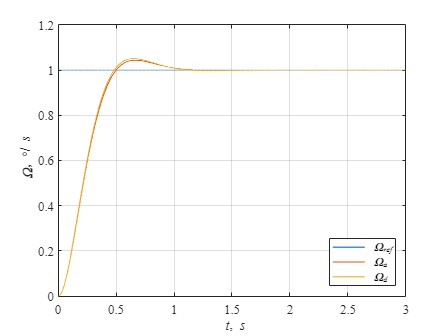

Tmdl = 3;
spl.Tu = ob.T1;
T0 = 0.1 *spl.Tu; %вот тут надо менять, чтобы заполнить табличку

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

warning off
b = sim('Lab5p1b','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it \Omega\rm, \circ/\it s')
legend ('\it \Omega_{ref}', '\it \Omega_a','\it \Omega_d', 'location', 'best')

Рисунок 1. Моделирование системы.

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса tp1 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp1 5% зоны: 4.0*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса tp2 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp2 5% зоны: 6.3*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 5.0%


#### T0 = 0.5Tu

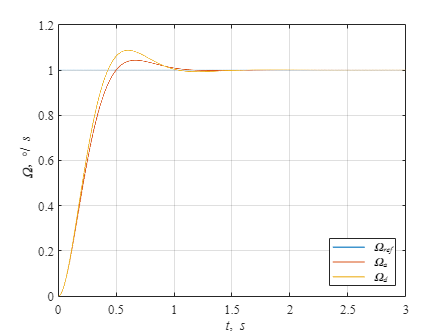

Tmdl = 3;
spl.Tu = ob.T1;
T0 = 0.5 *spl.Tu; 

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

warning off
b = sim('Lab5p1b','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it \Omega\rm, \circ/\it s')
legend ('\it \Omega_{ref}', '\it \Omega_a','\it \Omega_d', 'location', 'best')

Рисунок 2. Моделирование системы.

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса tp1 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp1 5% зоны: 3.7*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса tp2 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp2 5% зоны: 7.4*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 8.7%


#### T0 = Tu

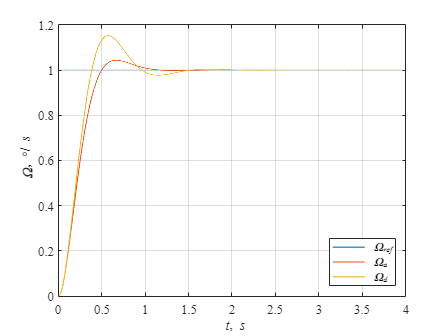

Tmdl = 4;
spl.Tu = ob.T1;
T0 = 1 *spl.Tu; %вот тут надо менять, чтобы заполнить табличку

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

warning off
b = sim('Lab5p1b','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it \Omega\rm, \circ/\it s')
legend ('\it \Omega_{ref}', '\it \Omega_a','\it \Omega_d', 'location', 'best')

Рисунок 3. Моделирование системы.

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса tp1 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp1 5% зоны: 3.4*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса tp2 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp2 5% зоны: 7.8*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 15.2%


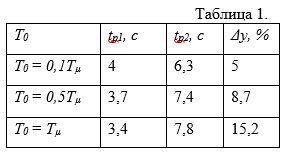

## 2. Cинтез системы из условия получения в ней стандартной настройки на "оптимум по модулю" с использованием эквивалентной непрерывной системы.

### Апроксимация апереодическим звеном

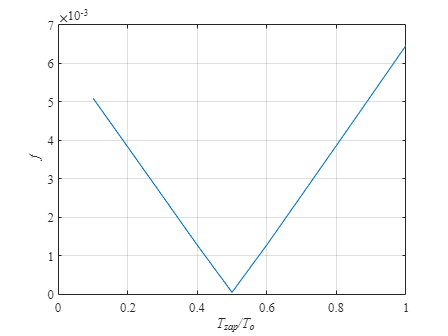

Tmdl = 1;
for i=1:10
    spl.Tz=i/10*T0;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('Lab5p2','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 
h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/T0,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')
xlim([0 1])

Рисунок 4. Функционал качества.

### Синтез цифрового ПИ-регулятора методом переоборудования 

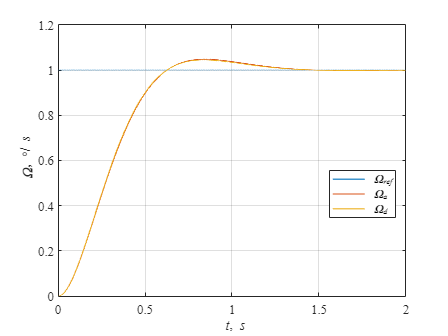

Tmdl = 2;
T0 = 1 *ob.T1;

spl.Tz = 0.5*T0;%сюда свое значение
spl.Tu = ob.T1 + spl.Tz;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);


warning off
b = sim('Lab5p2','ReturnWorkspaceOutputs', 'on', 'AlgebraicLoopMsg', 'off') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it \Omega\rm, \circ/\it s')
legend ('\it \Omega_{ref}', '\it \Omega_a','\it \Omega_d', 'location', 'best')

Рисунок 5. Моделирование системы.

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса tp1 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp1 5% зоны: 3.5*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса tp2 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp2 5% зоны: 3.5*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 4.5%


## **3. Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 ****>> Т****0****,**  **Т****2 ****>> Т****0 ****, ε = 0.**

### **Синтез регулятора скорости**

syms Tu T1
Wob = Kob/(T1*s+1)/(T2*s+1);
Wol = 1/(2*Tu*s*(Tu*s+1));
Wreg = Wol/Wob;
disp(simplify(collect(Wreg,s)))

$$\frac{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)}{2\,\mathrm{Kob}\,\mathrm{Tu}\,s\,\left(\mathrm{Tu}\,s+1\right)}$$

### Моделирование работы системы, настроенной на "технический оптимум"

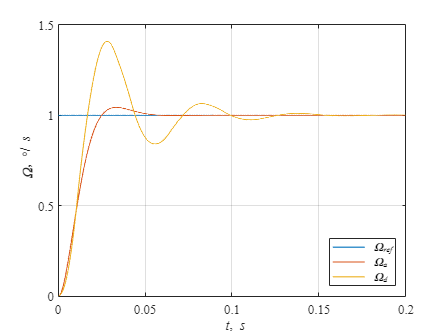

Tmdl = 0.2;

T0 = 0.1 *ob.T1;
spl.Tur = 0.5*T0;
spl.Tu = spl.Tur;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpa2 = 1;
spl.Kda2 = ob.T1;


spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);
spl.Kd2dg = 1/(exp(T0/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('Lab5p3','ReturnWorkspaceOutputs', 'on', 'AlgebraicLoopMsg', 'off') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it \Omega\rm, \circ/\it s')
legend ('\it \Omega_{ref}', '\it \Omega_a','\it \Omega_d', 'location', 'best')

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса tp1 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp1 5% зоны: 3.0*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса tp2 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp2 5% зоны: 16.7*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 40.6%


### Апроксимация

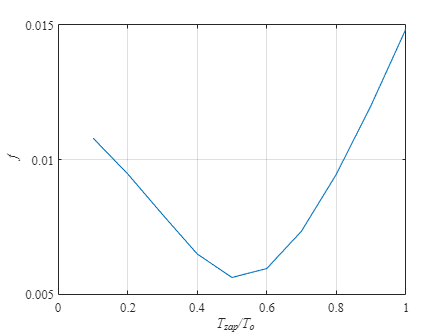

Tmdl = 0.1;
for i=1:20
    spl.Tz=i/10*T0;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('Lab5p3b','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 
h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/T0,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')
xlim([0 1])

### Синтез цифрового регулятора скорости методом переоборудования.

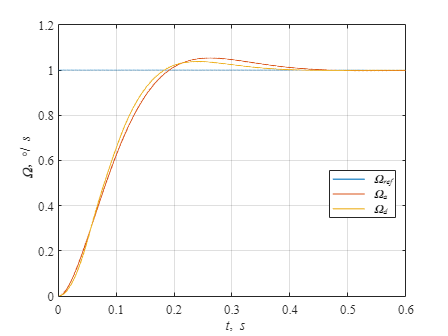

Tmdl = 0.6;

T0 = 0.5 *ob.T1;  %Тут меняем 
spl.Tz = 0.5*T0;
spl.Tur = 0.5*T0;
spl.Tu = spl.Tur + spl.Tz;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);
spl.Kpa2 = 1;
spl.Kda2 = ob.T1;

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

spl.Kd2dg = 1/(exp(T0/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('Lab5p3b','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it \Omega\rm, \circ/\it s')
legend ('\it \Omega_{ref}', '\it \Omega_a','\it \Omega_d', 'location', 'best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса tp1 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp1 5% зоны: 3.0*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса tp2 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp2 5% зоны: 3.0*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 3.8%


## **4. Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 ****>> Т****0****,**  **Т****2 ****>> Т****0 ****, ε = *****Т******0*****.**

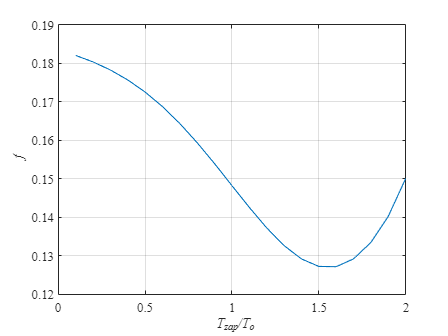

%Тоже самое, что и в прошлом пункте, только с запаздывание на один такт
Tmdl = 1;
for i=1:20
    spl.Tz=i/10*T0;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('Lab5p4','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 
h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/T0,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')

### Синтез цифрового ПД ПИ регулятора скорости методом переоборудования.

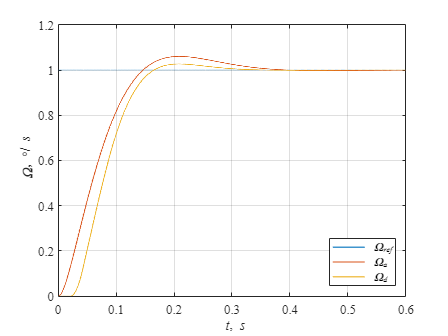

Tmdl = 0.6;

T0 = 0.2 *ob.T1;
spl.Tz = 1.6*T0;%меняем
spl.Tur = 0.5*T0;
spl.Tu = spl.Tur + spl.Tz;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);
spl.Kpa2 = 1;
spl.Kda2 = ob.T1;

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);

spl.Kd2dg = 1/(exp(T0/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('Lab5p4','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it \Omega\rm, \circ/\it s')
legend ('\it \Omega_{ref}', '\it \Omega_a','\it \Omega_d', 'location', 'best')

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса tp1 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp1 5% зоны: 3.2*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса tp2 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp2 5% зоны: 3.2*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 2.7%


## Моделирование работы системы настроенной на симметричный оптимум

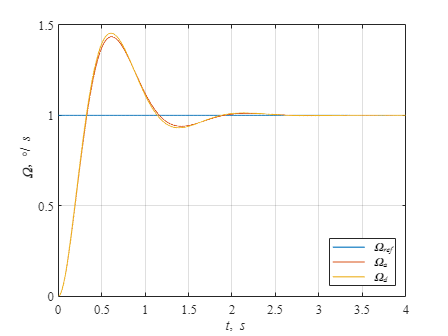

Tmdl = 4;
spl.Tu = ob.T1;
T0 = 0.1 *spl.Tu;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);

warning off
b = sim('Lab52p1b','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it \Omega\rm, \circ/\it s')
legend ('\it \Omega_{ref}', '\it \Omega_a','\it \Omega_d', 'location', 'best')


t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса tp1 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp1 5% зоны: 2.9*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса tp2 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp2 5% зоны: 14.8*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 45.4%


### Апроксимация апереодическим звеном

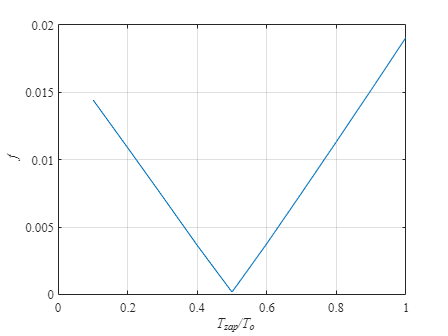

Tmdl = 2;
for i=1:10
    spl.Tz=i/10*T0;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('Lab52p2','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 
h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/T0,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')
xlim([0 1])

### Синтез цифрового ПИ-регулятора методом переоборудования

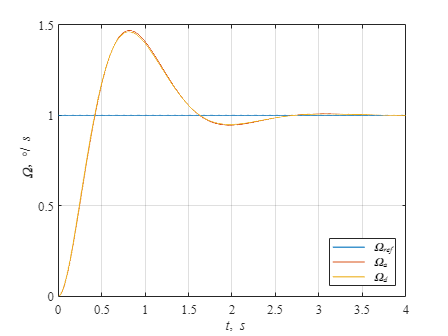

Tmdl = 4;
T0 = 1 *ob.T1;

spl.Tz = 0.5*T0;
spl.Tu = ob.T1 + spl.Tz;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);


warning off
b = sim('Lab52p2','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it \Omega\rm, \circ/\it s')
legend ('\it \Omega_{ref}', '\it \Omega_a','\it \Omega_d', 'location', 'best')


t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса tp1 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp1 5% зоны: 2.5*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса tp2 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp2 5% зоны: 12.6*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 46.2%


### **Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 ****>> Т****0****,**  **Т****2 ****>> Т****0 ****, ε = 0.**

#### **Синтез регулятора скорости**

syms Tu T1
Wob = Kob/(T1*s+1)/(T2*s+1);
Wol = (4*Tu*s+1)/(8*Tu^2*s^2*(Tu*s+1));
Wreg = Wol/Wob;
disp(simplify(collect(Wreg,s)))

$$\frac{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)\,\left(4\,\mathrm{Tu}\,s+1\right)}{8\,\mathrm{Kob}\,{\mathrm{Tu}}^{2}\,s^{2}\,\left(\mathrm{Tu}\,s+1\right)}$$

#### Моделирование работы системы настроенной на "технический оптимум"

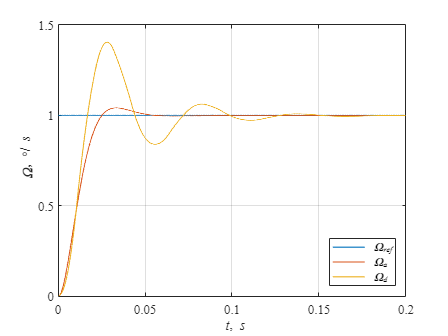

Tmdl = 0.2;

T0 = 0.1 *ob.T1;
spl.Tur = 0.5*T0;
spl.Tu = spl.Tur;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);
spl.Kpa2 = 1;
spl.Kda2 = ob.T1;




spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);
spl.Kd2dg = 1/(exp(T0/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('Lab52p3','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it \Omega\rm, \circ/\it s')
legend ('\it \Omega_{ref}', '\it \Omega_a','\it \Omega_d', 'location', 'best')


t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время переходного процесса tp1 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp1 5% зоны: 3.0*Tu

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время переходного процесса tp1 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время переходного процесса tp1 5% зоны: 16.7*Tu

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 40.6%


#### Апроксимация

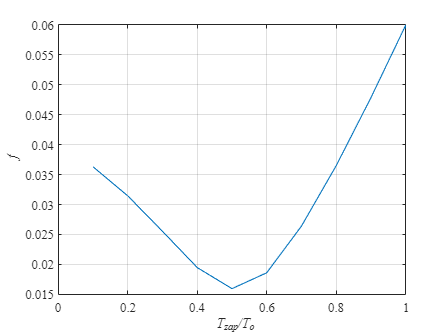

Tmdl = 0.1;
for i=1:10
    spl.Tz=i/10*T0;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('Lab52p3b','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 
h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/T0,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')
xlim([0 1])

#### Синтез цифрового регулятора скорости методом переоборудования

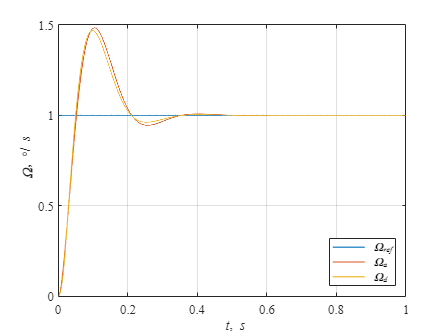

Tmdl = 1;

T0 = 0.2 *ob.T1;
spl.Tz = 0.5*T0;
spl.Tur = 0.5*T0;
spl.Tu = spl.Tur + spl.Tz;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);
spl.Kpa2 = 1;
spl.Kda2 = ob.T1;




spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);
spl.Kd2dg = 1/(exp(T0/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('Lab52p3b','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it \Omega\rm, \circ/\it s')
legend ('\it \Omega_{ref}', '\it \Omega_a','\it \Omega_d', 'location', 'best')

**Вывод**: Была синтезирована и исследована система управления с объектом в виде двух последовательно включенных апериодических звеньев первого порядка из условия обеспечения заданного по качеству переходного процесса: Технический и Симетричный отпимумы. Симетричный оптимум показал хуже по показателям, чем технический, это также подтверждает теорию. При увеличении T0 параметры переходных процессов тоже растут.